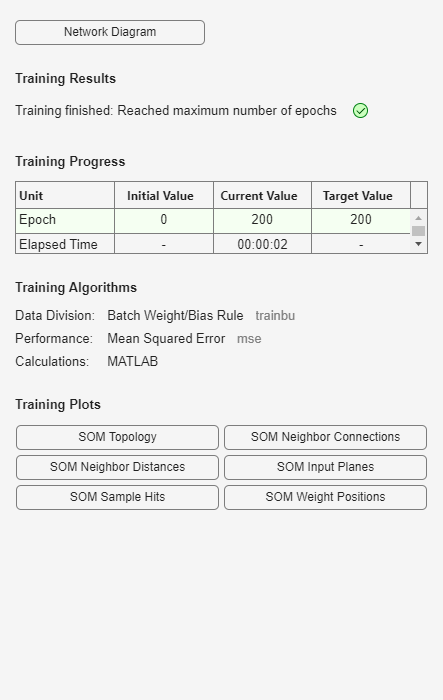

% 脚本假设输入向量已加载到工作区中。要显示命令行操作，
% 您可以使用不同于 GUI 操作所用的数据集。
% 以花卉数据集为例。鸢尾花数据集由 150 个四元素输入向量组成。

load iris_dataset
inputs = irisInputs;
% 创建一个网络。对于此示例，使用自组织映射 (SOM)。
% 此网络的一个层的神经元以网格形式组织。（有关详细信息，请参阅自组织特征映射。）
% 使用 selforgmap 创建网络时，请指定网格的行数和列数：
dimension1 = 10;
dimension2 = 10;
net = selforgmap([dimension1 dimension2]);
% 训练网络。SOM 网络使用默认的批量 SOM 算法进行训练。

[net,tr] = train(net,inputs);

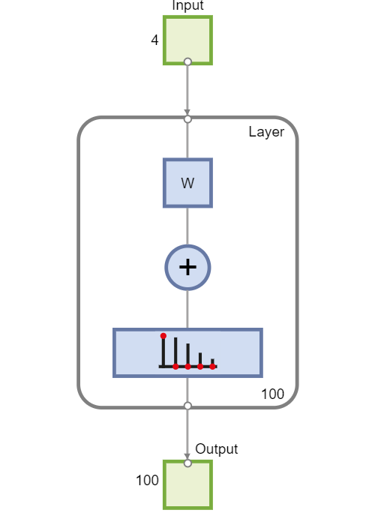

% 在训练期间，训练窗口会打开并显示训练进度。要随时中断训练，请点击 Stop Training。


% 测试网络。您可以使用经过训练的网络来计算网络输出。
outputs = net(inputs);
% 查看网络图。

view(net)

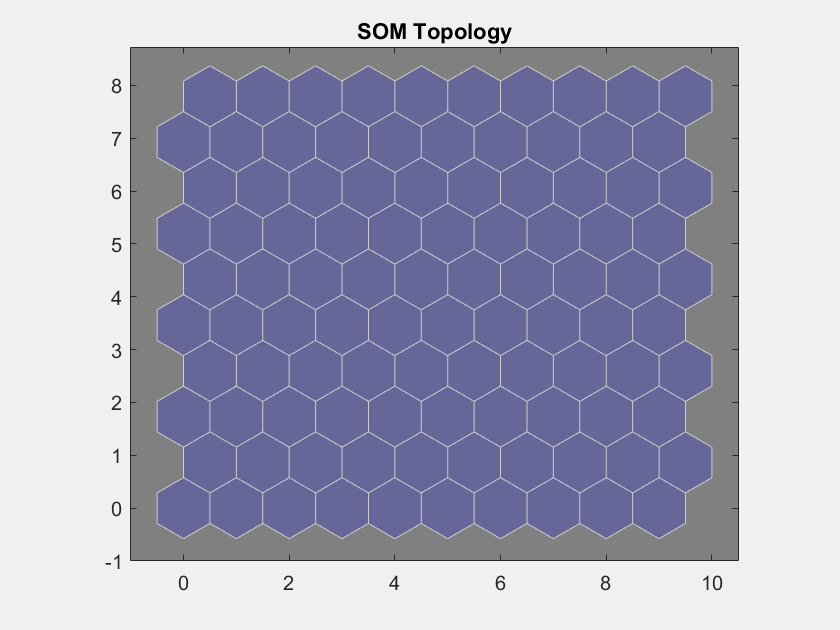



% 对于 SOM 训练，与每个神经元关联的权重向量都会朝着成为输入向量簇中心的方向移动。此外，拓扑中彼此相邻的神经元也应在输入空间中相互靠近，因此可以在网络拓扑的两个维度中可视化高维输入空间。默认的 SOM 拓扑是六边形的；要进行查看，请输入以下命令。

figure
plotsomtop(net)


% 
% 在此图中，每个六边形表示一个神经元。网格为 10×10，因此在此网络中总共有 100 个神经元。
% 每个输入向量中有四个元素，因此输入空间是四维的。权重向量（簇中心）在此空间内。
% 由于此 SOM 具有二维拓扑，因此可以用两个维度来可视化四维簇中心之间的关系。
% SOM 的一个可视化工具是权重距离矩阵（也称为 U 矩阵）。
% 要查看 U 矩阵，请在训练窗口中点击 SOM Neighbor Distances。
% 在下图中，蓝色六边形表示神经元。红线连接相邻的神经元。包含红线的区域中的颜色指示神经元之间的距离。
% 颜色越深，表示距离越远；颜色越浅，表示距离越近。一条深色带从底部中心区域延伸至右上角区域。
% SOM 网络看上去已将花卉聚类成两个不同的组。
% 
% 要进一步熟悉命令行操作，请尝试以下任务：
% 在训练期间，打开绘图窗口（如 SOM 权重位置图），并观察其动画效果。
% 从命令行使用 plotsomhits、plotsomnc、plotsomnd、plotsomplanes、plotsompos 和 plotsomtop 等函数绘图。
% （有关使用这些函数的详细信息，请参阅其参考页。）